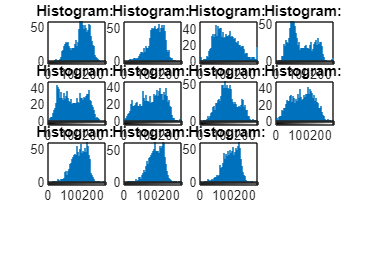

% Set the directory where the images are located
imageDir = 'C:\Users\apraj\OneDrive\Desktop\SMART INDIA HACKATHON\dataset\test\Defective';  % Replace with your local path

% Get a list of all JPG files in the directory
imageFiles = dir(fullfile(imageDir, '*.jpg'));

% Check if there are any images
if isempty(imageFiles)
    error('No JPG images found in the specified directory.');
end

% Initialize a cell array to store the images
images = cell(1, length(imageFiles));

% Load and store images
for i = 1:length(imageFiles)
    img = imread(fullfile(imageDir, imageFiles(i).name));
    % Resize the image to reduce resolution (e.g., 64x64)
    img = imresize(img, [64 64]);
    images{i} = img;  % Store the image in the cell array
end

% Generate histograms for all images
figure;
for i = 1:length(imageFiles)
    % Convert image to grayscale if not already
    if size(images{i}, 3) == 3
        imgGray = rgb2gray(images{i});
    else
        imgGray = images{i};
    end
    
    % Generate histogram
    subplot(ceil(sqrt(length(imageFiles))), ceil(sqrt(length(imageFiles))), i);
    imhist(imgGray);
    title(['Histogram: ']);
end

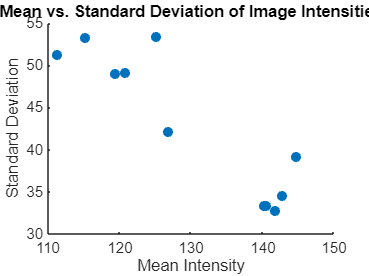


% Initialize arrays to store features
means = zeros(1, length(imageFiles));
stds = zeros(1, length(imageFiles));

% Extract features from images
for i = 1:length(imageFiles)
    if size(images{i}, 3) == 3
        imgGray = rgb2gray(images{i});
    else
        imgGray = images{i};
    end
    
    means(i) = mean(imgGray(:));
    stds(i) = std(double(imgGray(:)));
end

% Plot the means and standard deviations
figure;
scatter(means, stds, 'filled');
xlabel('Mean Intensity');
ylabel('Standard Deviation');
title('Mean vs. Standard Deviation of Image Intensities');

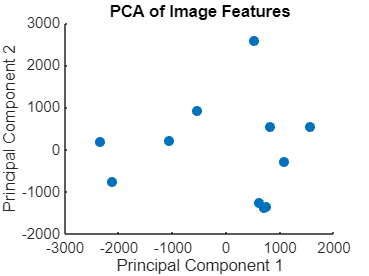


% Flatten the images and create a feature matrix
features = [];
for i = 1:length(images)
    if size(images{i}, 3) == 3
        imgGray = rgb2gray(images{i});
    else
        imgGray = images{i};
    end
    % Convert the flattened image to double
    features = [features; double(imgGray(:))'];
end

% Apply PCA to reduce dimensionality
[coeff, score, ~] = pca(features);

% Plot the first two principal components
figure;
scatter(score(:,1), score(:,2), 'filled');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA of Image Features');

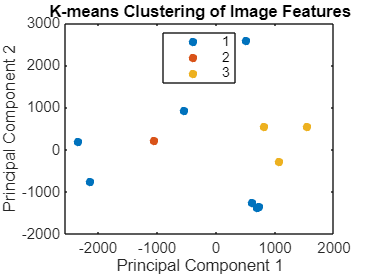


% Apply K-means clustering
numClusters = 3;  % Number of clusters
idx = kmeans(features, numClusters);

% Plot the clusters using the first two PCA components
figure;
gscatter(score(:,1), score(:,2), idx);
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('K-means Clustering of Image Features');

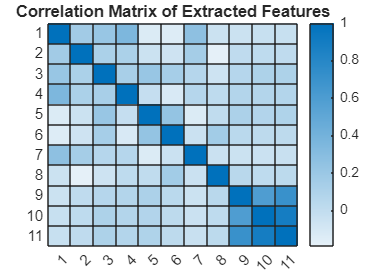


% Compute the correlation matrix of the features
correlationMatrix = corr(features');

% Visualize the correlation matrix as a heatmap
figure;
heatmap(correlationMatrix);
title('Correlation Matrix of Extracted Features');